% (asin(x)+2*x*y)*dx+(x^2+1+atan(y))*dy=0

clear
% 1)
% y'=-(asin(x)+2*x*y)/(x^2+1+atan(y))
syms x y(x)
eqn=diff(y(x))==-(asin(x)+2*x*y)/(x^2+1+atan(y))

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=-\frac{\mathrm{asin}\left(x\right)+2\,x\,y\left(x\right)}{\mathrm{atan}\left(y\left(x\right)\right)+x^{2}+1}$$

ySol=dsolve(eqn)

$$ySol = \mathrm{solve}\left(y\,x^{2}+y-\frac{\log\left(y^{2}+1\right)}{2}+y\,\mathrm{atan}\left(y\right)=-C_{5}-x\,\mathrm{asin}\left(x\right)-\sqrt{1-x^{2}},y\right)$$

% solve(y*x^2 + y - log(y^2 + 1)/2 + y*atan(y) == - C5 - x*asin(x) - (1 - x^2)^(1/2), y)
% y*x^2 + y - log(y^2 + 1)/2 + y*atan(y) == - C5 - x*asin(x) - (1 - x^2)^(1/2)

% 2)
syms x y
P(x,y)=asin(x)+2*x*y

$$P(x, y) = \mathrm{asin}\left(x\right)+2\,x\,y$$

Q(x,y)=x^2+1+atan(y)

$$Q(x, y) = x^{2}+\mathrm{atan}\left(y\right)+1$$

f=diff(P,y)-diff(Q,x)

$$f(x, y) = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P(x,y),x)+C(y)

$$U = C\left(y\right)+x^{2}\,y+x\,\mathrm{asin}\left(x\right)+\sqrt{1-x^{2}}$$

% C(y) + x^2*y + x*asin(x) + (1 - x^2)^(1/2)
dUy=diff(U,y)

$$dUy = \frac{\partial }{\partial y}C\left(y\right)+x^{2}$$

% x^2 + diff(C(y), y)
dCy=simplify(dUy-Q)

$$dCy(x, y) = \frac{\partial }{\partial y}C\left(y\right)-\mathrm{atan}\left(y\right)-1$$

% diff(C(y), y) - atan(y) - 1
C(y)=int(atan(y) + 1,y)

$$C(y) = y-\frac{\log\left(y^{2}+1\right)}{2}+y\,\mathrm{atan}\left(y\right)$$

% y - log(y^2 + 1)/2 + y*atan(y)
% y - log(y^2 + 1)/2 + y*atan(y)+ x^2*y + x*asin(x) + (1 - x^2)^(1/2) = C1

% 3)
x0=0;y0=0;
U=simplify(int(P(x,y),x,x0,x)+int(subs(Q(x,y),x,x0),y,y0,y))

$$U = y-\frac{\log\left(y^{2}+1\right)}{2}+x^{2}\,y+x\,\mathrm{asin}\left(x\right)+y\,\mathrm{atan}\left(y\right)+\sqrt{1-x^{2}}-1$$

syms C
eq2=U==C

$$eq2 = y-\frac{\log\left(y^{2}+1\right)}{2}+x^{2}\,y+x\,\mathrm{asin}\left(x\right)+y\,\mathrm{atan}\left(y\right)+\sqrt{1-x^{2}}-1=C$$

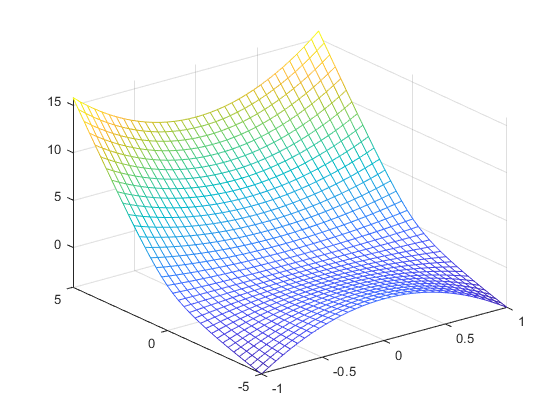

fmesh(U)